% Einlesen des Hypercubes
if ~exist('hcube', 'var')
    hcube = hypercube('C:\Users\teres\Documents\01_Hochschule\Master\2_research\05_Rohdaten\Messungen_HSI_230609\weissabgeglichen\PP_HDPE_PET_LDPE_SWIR_640_SN7515_11989us_2023-06-09T171806_raw_rad_ref_float32.img'); 
end
% Einlesen des Headerfiles
headerfile = 'C:\Users\teres\Documents\01_Hochschule\Master\2_research\05_Rohdaten\Messungen_HSI_230609\weissabgeglichen\PP_HDPE_PET_LDPE_SWIR_640_SN7515_11989us_2023-06-09T171806_raw_rad_ref_float32.hdr';
info = enviinfo(headerfile);
% Extrahiere Wellenlängeninformationen
wavelengths = info.Wavelength;

% Definition der Bereiche im Hypercube nach Material
data_PP = hcube.DataCube(276:295, 285:334, :);
data_HDPE = hcube.DataCube(965:984,285:334,  :);
data_LDPE = hcube.DataCube(2255:2274,285:334,  :);
data_PET = hcube.DataCube(1567:1586, 285:334, :);
data_PS = hcube.DataCube(2978:2997, 285:334, :);

% Extrahieren der Reflektanzwerte nach Material
spectra2D_PP = reshape(data_PP, [], size(data_PP, 3));
spectra2D_HDPE = reshape(data_HDPE, [], size(data_HDPE, 3));
spectra2D_LDPE = reshape(data_LDPE, [], size(data_LDPE, 3));
spectra2D_PET = reshape(data_PET, [], size(data_PET, 3));
spectra2D_PS = reshape(data_PS, [], size(data_PS, 3));

% Wie viele Spektren sollen pro Material verwendet werden
anzahl = 100; % Maximal 1000
allSpectra2D = cat(1, spectra2D_HDPE(1:anzahl, :), spectra2D_LDPE(1:anzahl, :), spectra2D_PET(1:anzahl, :), spectra2D_PP(1:anzahl, :), spectra2D_PS(1:anzahl, :));
indexArray = repmat(1:5, anzahl, 1);
indexArray = indexArray(:);

% Zentrale Wellenlaengen der Filter
filter_wl = [1150, 1200,1250, 1400];
% Bereiche der Filter initiieren
filter_regions = zeros(length(filter_wl), 2);

% Halbwertsbreite Filter
fwhm = 10;
hbf = fwhm/2;
for i = 1:length(filter_wl)
    filter_regions(i,1) = filter_wl(i)-hbf;
    filter_regions(i,2) = filter_wl(i)+hbf;
end

integral_values = zeros(size(allSpectra2D,1), length(filter_regions));
a = 0;
ymin = inf;
ymax = -inf;

% Iteriere durch alle Spektren
for i = 1:size(allSpectra2D,1)
    df = allSpectra2D(i,:);
    ymin = min(ymin, min(df));
    ymax = max(ymax, max(df));

    % Funktion erstellen durch Interpolation
    interp_function = @(x) interp1(wavelengths, df, x, 'linear', 'extrap');
    % Berechnung des Integrals fuer jeden Bereich
    for j = 1:length(filter_regions)
        fun = interp_function;
        integral_value = integral(fun, filter_regions(j,1), filter_regions(j,2));
        
        % Ueberpruefung ob Integralwert größer als 10 ist -> Ausreisser
        if integral_value <= 10
            integral_values(i,j) = integral_value;
        else
            a = a+1;
            break
        end
    end
end

% Leere Zeilen entfernen, falls es Ausreisser gab
integral_values = integral_values(1:end-a,:);
indexArray = indexArray(1:end-a,:);

disp('Integralwerte für jeden Bereich:');

Integralwerte für jeden Bereich:


disp(integral_values);

    1.8353    0.7524    1.2967    0.8000
    1.8478    0.7720    1.3208    0.8312
    1.8558    0.7832    1.3649    0.8504
    1.8133    0.7479    1.3122    0.7961
    1.8115    0.7470    1.2851    0.7868
    1.8334    0.7736    1.3081    0.8084
    1.8241    0.7564    1.2959    0.8037
    1.8098    0.7572    1.2889    0.7905
    1.8710    0.7846    1.3395    0.8507
    1.8813    0.7928    1.3563    0.8480
    1.8180    0.7529    1.2916    0.8090
    1.7566    0.7125    1.2279    0.7436
    1.7565    0.6964    1.2233    0.7301
    1.7599    0.7039    1.2350    0.7406
    1.8243    0.7645    1.2805    0.7901
    1.8231    0.7506    1.2869    0.8037
    1.8339    0.7659    1.3264    0.8353
    1.8550    0.7844    1.3324    0.8397
    1.8123    0.7501    1.2992    0.7981
    1.7860    0.7083    1.2501    0.7473
    1.7828    0.7326    1.2649    0.7830
    1.7990    0.7451    1.2912    0.7857
    1.8853    0.7937    1.3770    0.8547
    1.8302    0.7390    1.3085    0.8025
    1.7931    0.

latent =     1.3577
    0.2780
    0.0334
    0.0000


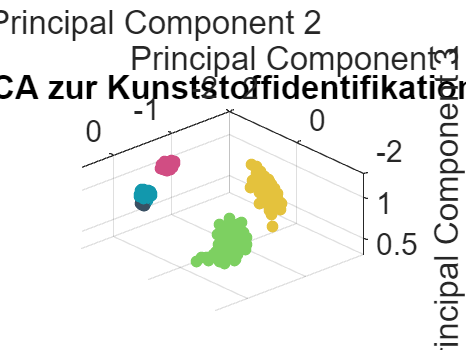

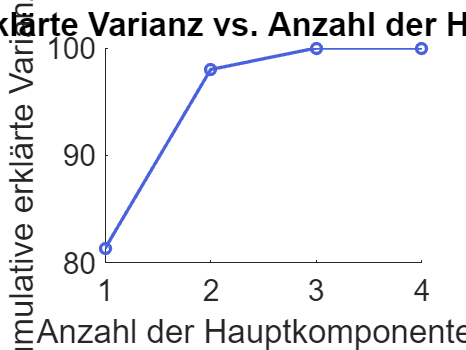

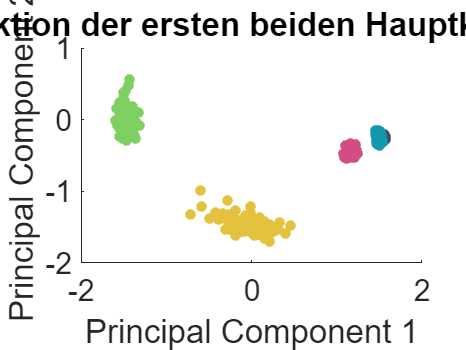


% Durchfuehren der PCA
[coeff, X_pca, y, centeredX] = pca_analysis(integral_values, indexArray);